# Principle Component Analysis

**Author**: Scott Campit

## Summary

**Dimensionality reduction** is a method to reduce the number of random variables under consideration. This is important, especially for:

- **Data visualization**: reducing the number of variables to the top 2 or 3 most important variables allows us to visualize these variables.

- **Data pre-processing**: if we want to use some models such as linear regression to maintain model interpretibility, we need can select features based on principle components.

## Principle Component Analysis

The remainder of this module focuses on **principle component analysis (PCA)** as our tool for dimensionality reducing from linear combinations of the original variables.

### Intuition of PCA

In a given dataset, variables may be highly correlated with each other (collinearity), which prevents us from using methods such as ordinary least squares. Additionally, these features have some redundancy and noise, which makes our dataset unnecessarily complex. Thus, we need some method to give us a better representation of the data that will allow us to use these "nice" methods and that will simplify our dataset.

One way to do this is to change the basis of our dataset **X** using another matrix **P** to output **Y**, which the best representation of our dataset (orthonormal).


$$\mathbf{PX}=\mathbf{Y}$$


**Interpretation:**

- **P** is a matrix that transforms **X** into **Y**. This will be a diagonal matrix of eigenvectors for each data entry.

- If we look at the data cloud geometrically, **P** is an application of rotation and stretch, such that we remove collinearity (from oval to circle).

This method that will give us a better representation of the data involves capturing the largest variance in the dataset, which is essentially trying to maximize the amount of information from the dataset while removing features that have unimportant features.

## Preliminary theory

We'll illustrate some preliminary theory by loading up the shME1 metabolomics dataset and applying PCA to it.

### Load dataset

We'll load TU8902 intracellular metabolomics data.

metabolomicsFile = '~/Data/Expression/Metabolomics/ME1/raw/ME1_Metabolomics.xlsx';
data = readtable(metabolomicsFile, 'Sheet', "TU8902 Intra")

data = 224×27 table
               CompoundMethod                c      e    g     l      m      n     r    x    TU8902ShNT_DoxDay5R1    TU8902ShNT_DoxDay5R2    TU8902ShNT_DoxDay5R3    TU8902ShNT_DoxDay5R1_1    TU8902ShNT_DoxDay5R2_1    TU8902ShNT_DoxDay5R3_1    TU8902ShME1_DoxDay1R1    TU8902ShME1_DoxDay1R2    TU8902ShME1_DoxDay1R3    TU8902ShME1_DoxDay3R1    TU8902ShME1_DoxDay3R2    TU8902ShME1_DoxDay3R3    TU8902ShME1_DoxDay5R1    TU8902ShME1_DoxDay5R2    TU8902ShME1_DoxDay5R3    TU8902ShME1_DoxDay5R1_1    TU8902ShME1_DoxDay5R2_1    TU8902Sh

### Covariance Matrix

Recall that the covariance matrix for a vector is the following: 


$$\textrm{cov}\left\lbrack X,X\right\rbrack =E\left\lbrack \left(X-\mu_X \right){\left(X-\mu_X \right)}^T \right\rbrack =E\left\lbrack {\textrm{XX}}^T \right\rbrack -\mu_X \mu_X^T$$


To construct a distance matrix, we can do this either by computing euclidean distances or correlations. I will do this using euclidean distances, because the interpretation will be simple: the closer two observations are, the less dissimilar they are.

#### Constructing the covariance matrix

Let's now construct the covariance matrix for one condition and time point: Day 1 shME1 +Dox in TU8902.

% Take the mean
shME1_Dox_1 = mean(table2array(...
                         data(:, ["TU8902ShME1_DoxDay1R1", ...

Z = 	1.0e+14 *

   -0.0712   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.2539    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   

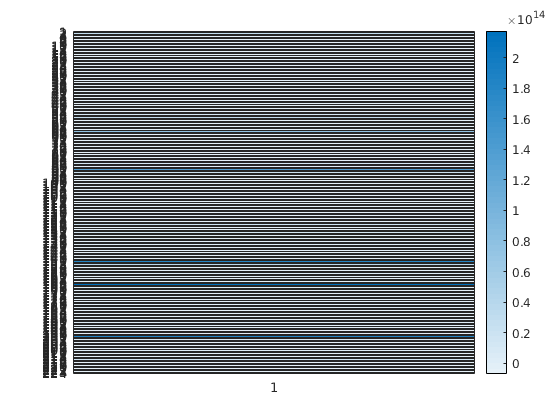

                                  "TU8902ShME1_DoxDay1R2", ...

                                  "TU8902ShME1_DoxDay1R3"])), 2);

% Find NaNs and assign to 0
shME1_Dox_1(isnan(shME1_Dox_1)) = 0;
                              
% Compute the mean
mu = mean(shME1_Dox_1);

% Compute the distance matrix, which is the covariance matrix.
E = shME1_Dox_1 - mu;
D = E .* E';

From now on, we'll be using the matrix D to perform matrix factorization or decomposition, due to its "nice" properties.

### Eigendecomposition

**Matrix decomposition** is all about finding the most important parts of a dataset by factorizing a matrix into simpler matrices. When we take the product of these simpler matrices, they can reconstruct the original matrix. This makes specific operations on a matrix easier to perform. 

Let $D$ be the original covariance matrix prior to factorization. **Eigendecomposition** is a method that breaks down a matrix into a diagonal matrix using **eigenvectors**, which are vectors denoting how much D should change to be orthonormal, and the amount that they change is the** eigenvalue.**

#### Singular value decomposition

The way we can perform an eigendecomposition of a matrix is to satisfy the following linear equation:


$$\mathbf{DV}=\mathit{\mathbf{U}}\Sigma \;\;$$


where U is a matrix representation of the eigenvalues and V are the eigenvectors, and $\Sigma$ is a diagonal matrix of singular values, where a singular value $\sigma=\sqrt{\lambda}$. If we write our covariance matrix in terms of these values, we get the equation:


$$D=U\Sigma V^T$$


To interpret this, this simply says that any matrix D can be converted to an orthogonal matrix (ie rotation or stretch), a diagonal matrix, and another orthogonal matrix (ie second rotation or stretch). Specifically, V is the rotation or stretch for the column space of D, and U is the rotation or stretch for the row space of D. 

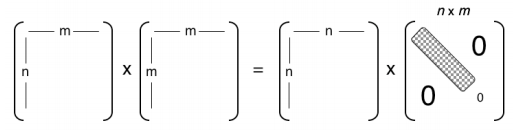

Taken from Shlens, 2014 A tutorial on PCA

Finally, to get the better representation of our dataset Z, we can compute the following expression:


$$Z=\mathrm{DV}$$


## Back to the dataset

Let's now compute the best representation of our dataset using singular value decomposition:

[U, S, V] = svd(D);
Z = D * V
heatmap(Z(:, 1))

## Advanced Theory

### Solving the PCA problem

This section reviews the derivation and solution of the PCA problem.

#### Langrange multiplers

In order to find the local maximum for the variance of a linear combination of features subject to some constraints, we need to use Lagrange multiplers. Langrange multiplers conver the constrained problem into a form where a derivative of an unconstrained problem can be applied. The general form of the optimization problem can be written as:


$$\begin{array}{l}
\max \;f\left(x,y\right)\\
\textrm{subject}\;\textrm{to}\;g\left(x,y\right)=c
\end{array}$$


The general form of the Langrange multiplier is shown below:


$$L\left(x,y,\lambda \right)=f\left(x,y\right)-\lambda g\left(x,y\right)$$


where we introduce a new variable $\lambda$, which may be added or subtracted. If there is a maximum or minimum for $f\left(x,y\right)$, there exists a value for $\lambda$ where the first partial derivatives of $L$is equal to 0. 

#### Back to the PCA problem

To compute the first principle component, we'll write the constrained $u_1^T u_1 =1$as Langrange multiplers: 


$$\max \;f\left(u_1 \right)=u_1^T \Sigma u_1 +\lambda_1 \left(1-u_1^T u_1 \right)$$


We now need to compute the partial derivative with respect to the weights, and set it equal to 0:


$$\frac{\vartheta f\left(w_1 \right)}{\vartheta w_1 }=2\left(\Sigma -\lambda_1 I\right)w_1 =0$$


We can do some algebraic wrangling to solve for $\lambda_{1}$. The solution must be one of the eigenvalues of $\Sigma$ and $w_1$ the corresponding eigenvector. The question is, how do we choose the best eigenvector to use?

Let $\Sigma =W\Lambda W^T$, where $W$is a $p\times p$ matrix of eigenvectors, and $\Lambda$ is a $p\times p$ diagonal matrix of eigenvalues.

The idea is that we want to pick an eigenvector $w_1$ such that ${w_1 }^T \Sigma w_1$is as large as possible. Thus, $\lambda_1$ has to be the largest eigenvalue of $\Sigma$.

The solution is given by the eigendecomposition of $\Sigma$:


$$\Sigma =W\Lambda W^T ,Z=W^T X$$


## Properties of principle components

Pirnciple components are linear combinations of optimally-weighted observed variables, which are less than or equal to the number of original variables. Some additional properties are described below

- Principle components are independent, assuming that $X$ is multivariate normal

- The $\textrm{Cov}\left(Z\right)=\Lambda$, so principle components are uncorrelated

### Total variance

The total variance contributed by principle components is


$$\begin{array}{l}
\sum_{j=1}^p \textrm{Var}\left(X_j \right)=\textrm{trace}\left(\Sigma \right)\;\;\;\;\;\;\;\;\;\;\;=\textrm{trace}\left(W\Lambda W^T \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\textrm{trace}\left(\Lambda W^T W\right)=\textrm{trace}\left(\Lambda \right)=\sum_{j=1}^p \lambda_i 
\end{array}$$


The $k^{\textrm{th}}$ projection $Z_k$ accounts for $\frac{\lambda_k }{\sum_{j-1}^p \lambda_j }$ proportion of the total variance of the original data in $X$.

## Principle component analysis terminology

$X$is a mean centered $n\times p$ data matrix, where each data point is represented by a row, and the sample covariance is used: $\Sigma^ˆ =\frac{X^T X}{n-1}$

The vectors $w_k$ are PC directions, and the coordinates $w_{\textrm{kj}}$ are loadings, which can also be defined as $\sqrt{\lambda_k }w_{\textrm{kj}}$.

The vectors $Z_k ={\textrm{Xw}}_k$ are principal components or scores, and are projections of the data onto the PC directions.

## Covariance versus correlation

Note that applying principle components using the correlation versus the covariance matrices are not the same, and have different interpretations.

The data needs to be mean centered to get a covariance matrix that is useful for transforming the data points. 

Alternatively, it is also possible to feature scale the data to have a mean of 0 and standard deviation of 1. This is equivalent to applying PCA to the correlation matrix. However, this does have implications in interpreting the data:

- One reason to standardize is that the analysis will be independent of the units

- However, another reason to not standardize is that there is information in the variance, particularly if all variables measured are on the same scale.

## How many principle components should we keep?

For visualizing principle components, we can really only use 2-3 principle components. However, if we want to think about dimension reduction, we need to consider the percentage of variance explained, so that we maximize the amount of information retained from each principle component:

$\textrm{POV}=\frac{\sum_{j=1}^k \lambda_j }{\sum_{j=1}^p \lambda_j }\ge 1-\alpha$, where $\alpha$ is a pre-defined threshold.

We can also visualize this using a scree plot, which plots $\lambda_k$ against $k$.

## Computing principle components using singular value decomposition

While it is possible to compute principle components using the covariance or correlation matrix, it does result from a lose of precision. Thus, in practice, **singular value decomposition (SVD)** is the method for obtaining a low rank approximation of our data.

SVD is a generalized method to factorize a matrix into a two unitary matrices ($U,V$), and a diagonal matrix $\Sigma \ldotp$ 


$$\textrm{SVD}\left(X\right)=U\Sigma V^T$$


From singular value decomposition, we can get PC scores using the following relationship:


$$Z=\textrm{XW}=U\Sigma$$


The data projected onto the first PC directions is the best rank $k$ approximation to the full data matrix $X$ in the Frobenius norm.

## Issues with PCA

- Principle components with equal variance: if the eigen values concide, their eigenspace is a unique k-dimensional subspace, but within the subspace, the PC directions cannot be distinguished

- Further, PCA is not a robust method, as it is sensitive to outliers

- To ease interpretation for high dimensional datasets, sparse variants of PCA are available

- If the covariance matrix is singular, then the $\textrm{rank}\left(\Sigma \right)$is defined. This is always the case when $p>n$, since the sample covariance matrix has rank $min(p, n-1)$

## Population versus sample PCA

Using PCA in practice, we need to estimate $\Sigma$ with the sample covariance matrix:


$$\Sigma^ˆ =\frac{1}{n-1}X^T X$$


The quality of the approximation varies when $p > n$.

## Implications of PCA

- The estimated eigenvalues are approximately normally distributed, and the estimated eigenvectors also converge to the truth

- Since all estimated eigenvalues are independent from the eigenvectors, this can be used to construct confidence intervals.

## Computational inference for PCA

The goals for PCA from a statistical perspective are the following:

- Obtain standard errors and confidence intervals for estimated parameters

- Test whether there is any structure in the data

## Fundamentals of Bootstrap

**Bootstrapping** is a method that can be applied to estimate parameters and assess variability when there is no theory to compute the standard errors, confidence intervals, or if the theory cannot be trusted.

### Bootstrap versus simulation

#### Simulation

A simulation is when we generated i.i.d copies of $X$, perform, PCA, and repeat $B$ times. We compute the mean and standard deviation of our eigenvalues and compare to the true $\Sigma$. While this is useful for testing new methodologies and asymptotics, it cannot be used to infer anything about a given dataset

#### Bootstrap

Bootstrap is when we do sampling with replacement to create a new sample, which can be used to compute standard errors and confidence intervals. This can be applied to assess the percentage of variance explained/

## The biplot

A biplot is a way to plot the observations and variables in the same plot.

### Properties of the biplot

- The variables are represented by directions

- Projecting points onto these directions gives you an idea about the original variable values

- Cosine angles between directions are proportional to correlations between variables

- If the first two components don't explain most of the variance, be cautious about interpretation.